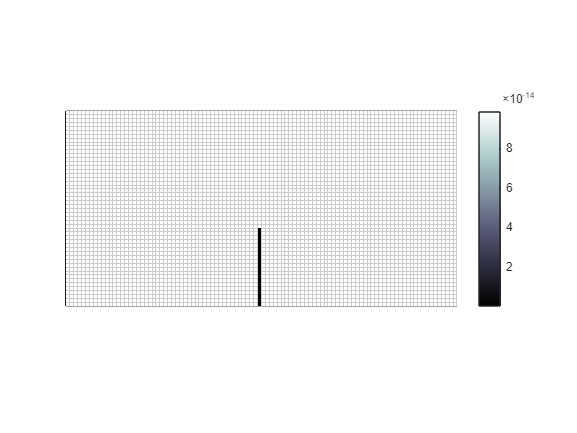

% Create Cartesian grid
G = cartGrid([100, 50, 1]);

% Plot grid without face color and with semi-transparent edges
plotGrid(G, 'FaceColor', 'none', 'EdgeAlpha', 0.5)

% Set axis properties
axis equal
axis tight
axis off

% Compute grid geometry
G = computeGeometry(G);

% Create rock properties
rock = makeRock(G, 100*milli*darcy, 0.25);

% Define fault
faultLength = 20;
ind = sub2ind([100, 50], repmat(50, 1, faultLength), 1:faultLength);
rock.perm(ind) = eps;

% Plot rock permeability
plotCellData(G, rock.perm, 'EdgeAlpha', 0.2)
colormap('bone')
colorbar

% Compute transmissibility
hT = computeTrans(G, rock);

% Initialize fluid properties
fluid = initSimpleFluid('mu', [1, 10], 'rho', [1000 1000], 'n', [2 2]);

% Set simulation time
T = 10*year;

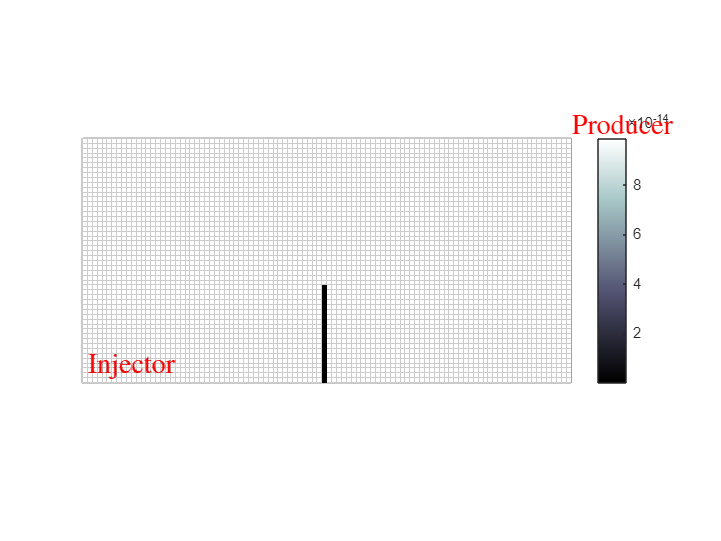

% Define injection rate
rate = sum(poreVolume(G, rock)) / T;

% Define injector well
W = addWell([], G, rock, 1, 'Type', 'rate', 'Val', rate, 'Name', 'Injector', 'Radius', 0.1, 'Comp_i', [1 0]);

% Define production well
W = addWell(W, G, rock, G.cells.num, 'Type', 'rate', 'Val', -rate, 'Name', 'Producer', 'Radius', 0.1, 'Comp_i', [0 1]);

% Plot wells
plotWell(G, W);

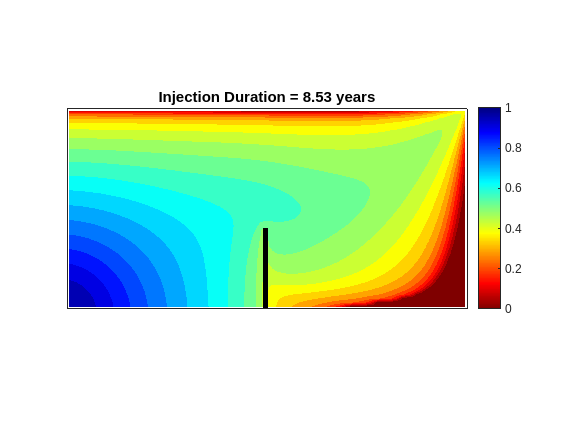

% Initialize reservoir state
state = initState(G, W, 100*barsa, [0 1]);
tsn = 300;
tsv = T/tsn;

% Main simulation loop
time = 0;
for i = 1:tsn
    % Perform incompressible two-point flux approximation
    state = incompTPFA(state, G, hT, fluid, 'Wells', W);
    
    % Perform implicit transport
    state = implicitTransport(state, G, tsv, rock, fluid, 'Wells', W);
      % Plotting results
    x = G.cells.centroids(:, 1);
    y = G.cells.centroids(:, 2);
    X = reshape(x, G.cartDims);
    Y = reshape(y, G.cartDims);
    Z = reshape(state.s(:, 1), G.cartDims);
    
    % Contour plot of saturation
    contourf(X, Y, Z, 20, 'EdgeColor', 'none');
    hold on;
    
    % Plot fault
    plotGrid(G, ind, 'FaceColor', 'k')
    
    % Set axis properties
    clim([0 1])
    axis equal
    axis([0 100 0 50])
    set(gca, 'XTick', [], 'YTick', [])
    colormap(flipud(jet))
    colorbar
    
    % Update time and title
    time = time + T / tsn;
    title(sprintf('Injection Duration = %.2f years', convertTo(time, year)))
    
    % Pause to display animation
    pause(0.01)
end